## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

% For different number of total vehicles, we may need to change the lower
% bound of the con0 in vehicle class for decentralization (0.001/0.0001)
rng(7)

Creation of the network of platoons

%% Setup
network_index = 0;                     % network Index
numOfPlatoons = 1;                     % num of platoons
numOfVehicles = [7]; %[4,5,6,7,8,10];    % num of vehicles in each platoon, for N=8, 10, the lower bound of the con0 is set as 0.001
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 5;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    desiredSeperation_k = [];

    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - vehicleSeperationMean - vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        

        % Desired vehicular positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + vehicleSeperationMean;

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        % noisemean_ki = rand(3,1);
        % noisestd_ki = 0.1*rand(3,1);

        noisemean_ki = rand(3,1)-0.5*ones(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

% Platoon simulation video figure setup
figure(1)
hold on 
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(1)

#### Synthesizing controllers for the platoon

**Configuration 1:** Centralized Stabilizing Control using Error Dynamics II

Note: Local passivating controller synthesis should not use a cost function in order to get a set of local controller gain coefficients that are smaller (and thus, practical).

% %%% Global controller synthesis specifications
% % Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
% errorDynamicsType = 2;  % Error dynamics formulation I or I
% isCentralized = 1;      % Centralized or decentralized controller synthesis
% isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)
% gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar  % Desired max noise attenuation
% 
% %%% Local passivating controller synthesis specifications 
% % LowerBound on \nu and upperBound on \rho 
% nuBar = -10;        % For the constraint: nu >= nuBar       %nuBar = -8.1
% rhoBar = 5;         % For the constraint: rho <= rhoBar     %rhoBar = 4.1

**Configuration 2:** Centralized Robust Control using Error Dynamics II

Note: In the local passivating controller synthesis, when no cost function is used, the resulting passivity indices are not amenable to global controller synthesis. 

To resolve this, we can resort to using the fundamental cost function for local passicating controller synthesis. However, this leads to: (Issue 1) larger local controller gains, and (Issue 2) global controller gains with no inter-vehicle interconnections. 

To solve the first issue, we can resort to use a cost function (in local passivating controller synthesis) of the form: 0.0000001*(- nu + rhoBar); This leads to relatively low local controller gains as well as passivity indices that are amenable to global controller synthesis. However, (Issue 2) is still a problem. 

%%% Global controller synthesis specifications
% Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
errorDynamicsType = 2;  % Error dynamics formulation I or I
isCentralized = 0;      % Centralized or decentralized controller synthesis
isDSS = 1;               % Involve DSS constraints (1) or not (0)
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
pVals = net.optimizeCodesignParameters(isCentralized,isDSS)

PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7503.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.3632.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.7117.
Global Synthesis Success with gammaSq=9.1061


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7503.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.3632.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal =   -69.5060  -86.9109  -16.2247


R_i =    84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.7117.


PVal =     0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal =     0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7736.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.7716.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.5885.
Global Synthesis Success with gammaSq=5.5885


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7736.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.7716.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.5885.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=4.0748.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.6414.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.6864.
Global Synthesis Success with gammaSq=4.6414


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=4.0748.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.6414.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.6864.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=4.9727.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.7324.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=5.3473.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.0037.
Global Synthesis Success with gammaSq=5.3473


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=4.9727.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.7324.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=5.3473.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.0037.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=7.4226.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.8404.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.1839.
Global Synthesis Success with gammaSq=9.1061


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=7.4226.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.8404.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.1839.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7503.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0788.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=6.3117.
Global Synthesis Success with gammaSq=9.1061


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7503.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0788.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=6.3117.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7503.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.3632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.5266.
Global Synthesis Success with gammaSq=9.1061


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 1 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 2 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 3 with gammaSq=9.1061.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.7503.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.3632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.5266.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    9.106105e+00    0.000e+00    2.996e+08


PVal = 3×3
    0.1841   -0.1367   -0.0048
   -0.1367    0.1583   -0.1962
   -0.0048   -0.1962    1.0442


KVal = 1×3
    0.1510   -0.3445   -3.2054


LVal = 1×3
  -33.2981  -45.5147  -11.7725


R_i = 3×3
   35.5704   40.2966    7.7328
   40.2966   53.8818   10.3066
    7.7328   10.3066    2.9292


Decentralized Synthesis Success at: 1 with gammaSq=3.6381.


PVal = 3×3
    0.2107   -0.1538   -0.0064
   -0.1538    0.1775   -0.2124
   -0.0064   -0.2124    1.0620


KVal = 1×3
    0.1622   -0.3784   -2.9425


LVal = 1×3
  -29.6569  -41.2329  -11.1964


R_i = 3×3
   30.6919   35.2577    7.2369
   35.2577   47.9118    9.7954
    7.2369    9.7954    2.9444


Decentralized Synthesis Success at: 2 with gammaSq=3.8026.


PVal = 3×3
    0.1909   -0.1411   -0.0052
   -0.1411    0.1633   -0.2005
   -0.0052   -0.2005    1.0494


KVal = 1×3
    0.1539   -0.3532   -3.1346


LVal = 1×3
  -32.3640  -44.4259  -11.6339


R_i = 3×3
   34.2686   38.9739    7.6147
   38.9739   52.3267   10.1889
    7.6147   10.1889    2.9370


Decentralized Synthesis Success at: 3 with gammaSq=4.3628.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=7.5296.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.9258.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.9213.


PVal = 3×3
    0.1841   -0.1367   -0.0048
   -0.1367    0.1583   -0.1962
   -0.0048   -0.1962    1.0442


KVal = 1×3
    0.1510   -0.3445   -3.2054


LVal = 1×3
  -33.2981  -45.5147  -11.7725


R_i = 3×3
   35.5704   40.2966    7.7328
   40.2966   53.8818   10.3066
    7.7328   10.3066    2.9292


Decentralized Synthesis Success at: 1 with gammaSq=3.6381.


PVal = 3×3
    0.2107   -0.1538   -0.0064
   -0.1538    0.1775   -0.2124
   -0.0064   -0.2124    1.0620


KVal = 1×3
    0.1622   -0.3784   -2.9425


LVal = 1×3
  -29.6569  -41.2329  -11.1964


R_i = 3×3
   30.6919   35.2577    7.2369
   35.2577   47.9118    9.7954
    7.2369    9.7954    2.9444


Decentralized Synthesis Success at: 2 with gammaSq=3.8026.


PVal = 3×3
    0.1909   -0.1411   -0.0052
   -0.1411    0.1633   -0.2005
   -0.0052   -0.2005    1.0494


KVal = 1×3
    0.1539   -0.3532   -3.1346


LVal = 1×3
  -32.3640  -44.4259  -11.6339


R_i = 3×3
   34.2686   38.9739    7.6147
   38.9739   52.3267   10.1889
    7.6147   10.1889    2.9370


Decentralized Synthesis Success at: 3 with gammaSq=4.3628.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=7.5296.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.9258.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.9213.
Global Synthesis Success with gammaSq=7.5296


PVal = 3×3
    0.1221   -0.0954   -0.0010
   -0.0954    0.1109   -0.1512
   -0.0010   -0.1512    0.9910


KVal = 1×3
    0.1172   -0.2640   -4.1086


LVal = 1×3
  -47.2400  -61.5419  -13.5856


R_i = 3×3
   55.1630   60.0148    9.2149
   60.0148   76.6818   11.7632
    9.2149   11.7632    2.8136


Decentralized Synthesis Success at: 1 with gammaSq=3.1795.


PVal = 3×3
    0.1315   -0.1018   -0.0017
   -0.1018    0.1184   -0.1586
   -0.0017   -0.1586    0.9987


KVal = 1×3
    0.1252   -0.2791   -3.9215


LVal = 1×3
  -43.8704  -57.7073  -13.1645


R_i = 3×3
   50.5001   55.2884    8.8651
   55.2884   71.2617   11.4097
    8.8651   11.4097    2.8281


Decentralized Synthesis Success at: 2 with gammaSq=8.6826.


PVal = 3×3
    0.1244   -0.0970   -0.0012
   -0.0970    0.1128   -0.1531
   -0.0012   -0.1531    0.9928


KVal = 1×3
    0.1193   -0.2679   -4.0580


LVal = 1×3
  -46.3232  -60.5030  -13.4742


R_i = 3×3
   53.8968   58.7324    9.1228
   58.7324   75.2167   11.6710
    9.1228   11.6710    2.8182


Decentralized Synthesis Success at: 3 with gammaSq=5.2948.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.4636.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.1317.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=8.3831.


PVal = 3×3
    0.1221   -0.0954   -0.0010
   -0.0954    0.1109   -0.1512
   -0.0010   -0.1512    0.9910


KVal = 1×3
    0.1172   -0.2640   -4.1086


LVal = 1×3
  -47.2400  -61.5419  -13.5856


R_i = 3×3
   55.1630   60.0148    9.2149
   60.0148   76.6818   11.7632
    9.2149   11.7632    2.8136


Decentralized Synthesis Success at: 1 with gammaSq=3.1795.


PVal = 3×3
    0.1315   -0.1018   -0.0017
   -0.1018    0.1184   -0.1586
   -0.0017   -0.1586    0.9987


KVal = 1×3
    0.1252   -0.2791   -3.9215


LVal = 1×3
  -43.8704  -57.7073  -13.1645


R_i = 3×3
   50.5001   55.2884    8.8651
   55.2884   71.2617   11.4097
    8.8651   11.4097    2.8281


Decentralized Synthesis Success at: 2 with gammaSq=8.6826.


PVal = 3×3
    0.1244   -0.0970   -0.0012
   -0.0970    0.1128   -0.1531
   -0.0012   -0.1531    0.9928


KVal = 1×3
    0.1193   -0.2679   -4.0580


LVal = 1×3
  -46.3232  -60.5030  -13.4742


R_i = 3×3
   53.8968   58.7324    9.1228
   58.7324   75.2167   11.6710
    9.1228   11.6710    2.8182


Decentralized Synthesis Success at: 3 with gammaSq=5.2948.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.4636.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.1317.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=8.3831.
Global Synthesis Success with gammaSq=8.6826


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.8067.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.044.


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.8067.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.044.
Global Synthesis Success with gammaSq=6.7626


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6175   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=7.1636.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=6.3086.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.3723.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.6834.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=6.041.
Global Synthesis Success with gammaSq=7.1636


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6175   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=7.1636.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=6.3086.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.3723.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.6834.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=6.041.


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=5.865.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.2321.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=5.1084.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.447.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.7582.
Global Synthesis Success with gammaSq=5.865


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=5.865.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.2321.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=5.1084.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.447.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.7582.


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2705  -14.5682


R_i = 3×3
   66.3242   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=6.1957.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0768.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.6057.
Global Synthesis Success with gammaSq=6.7626


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2705  -14.5682


R_i = 3×3
   66.3242   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=6.1957.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0768.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.6057.


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=6.8711.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.374.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.7547.
Global Synthesis Success with gammaSq=6.8711


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=6.8711.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.374.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.7547.


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.8067.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.3408.
Global Synthesis Success with gammaSq=6.7626


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.8067.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.3408.


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.8067.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.5166.
Global Synthesis Success with gammaSq=6.7626


PVal = 3×3
    0.1049   -0.0837   -0.0003
   -0.0837    0.0966   -0.1367
   -0.0003   -0.1367    0.9876


KVal = 1×3
    0.1030   -0.2396   -4.5948


LVal = 1×3
  -57.0984  -72.7794  -14.7409


R_i = 3×3
   67.8498   73.0974   10.1354
   73.0974   91.6176   12.7000
   10.1354   12.7000    2.7730


Decentralized Synthesis Success at: 1 with gammaSq=3.0655.


PVal = 3×3
    0.1099   -0.0870   -0.0000
   -0.0870    0.1012   -0.1411
   -0.0000   -0.1411    0.9802


KVal = 1×3
    0.1032   -0.2386   -4.4140


LVal = 1×3
  -51.5733  -66.3110  -14.0525


R_i = 3×3
   61.5710   66.2600    9.5422
   66.2600   83.6732   12.0495
    9.5422   12.0495    2.7555


Decentralized Synthesis Success at: 2 with gammaSq=6.7626.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5632.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 4 with gammaSq=4.8067.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.044.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.5166.
    1      16    6.762649e+00    0.000e+00    6.024e+07    6.040e-02


PVal = 3×3
    0.0891   -0.0722   -0.0001
   -0.0722    0.0831   -0.1219
   -0.0001   -0.1219    0.9664


KVal = 1×3
    0.0923   -0.2152   -5.1235


LVal = 1×3
  -68.3578  -85.6203  -16.1028


R_i = 3×3
   82.7111   88.2032   11.1278
   88.2032  108.8329   13.7296
   11.1278   13.7296    2.7668


Decentralized Synthesis Success at: 1 with gammaSq=3.0457.


PVal = 3×3
    0.1477   -0.1127   -0.0027
   -0.1127    0.1310   -0.1709
   -0.0027   -0.1709    1.0139


KVal = 1×3
    0.1350   -0.3004   -3.6601


LVal = 1×3
  -39.6929  -52.9173  -12.6362


R_i = 3×3
   44.5800   49.3507    8.4379
   49.3507   64.4168   10.9904
    8.4379   10.9904    2.8615


Decentralized Synthesis Success at: 2 with gammaSq=8.7847.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=3.8209.


PVal = 3×3
    0.0843   -0.0686    0.0000
   -0.0686    0.0789   -0.1171
    0.0000   -0.1171    0.9584


KVal = 1×3
    0.0880   -0.2062   -5.3181


LVal = 1×3
  -71.4652  -89.1106  -16.4299


R_i = 3×3
   87.1337   92.4956   11.2936
   92.4956  113.6694   13.8795
   11.2936   13.8795    2.7382


Decentralized Synthesis Success at: 4 with gammaSq=4.1538.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.6468.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.4936.


PVal = 3×3
    0.0891   -0.0722   -0.0001
   -0.0722    0.0831   -0.1219
   -0.0001   -0.1219    0.9664


KVal = 1×3
    0.0923   -0.2152   -5.1235


LVal = 1×3
  -68.3578  -85.6203  -16.1028


R_i = 3×3
   82.7111   88.2032   11.1278
   88.2032  108.8329   13.7296
   11.1278   13.7296    2.7668


Decentralized Synthesis Success at: 1 with gammaSq=3.0457.


PVal = 3×3
    0.1477   -0.1127   -0.0027
   -0.1127    0.1310   -0.1709
   -0.0027   -0.1709    1.0139


KVal = 1×3
    0.1350   -0.3004   -3.6601


LVal = 1×3
  -39.6929  -52.9173  -12.6362


R_i = 3×3
   44.5800   49.3507    8.4379
   49.3507   64.4168   10.9904
    8.4379   10.9904    2.8615


Decentralized Synthesis Success at: 2 with gammaSq=8.7847.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=3.8209.


PVal = 3×3
    0.0843   -0.0686    0.0000
   -0.0686    0.0789   -0.1171
    0.0000   -0.1171    0.9584


KVal = 1×3
    0.0880   -0.2062   -5.3181


LVal = 1×3
  -71.4652  -89.1106  -16.4299


R_i = 3×3
   87.1337   92.4956   11.2936
   92.4956  113.6694   13.8795
   11.2936   13.8795    2.7382


Decentralized Synthesis Success at: 4 with gammaSq=4.1538.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.6468.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.4936.
Global Synthesis Success with gammaSq=8.7847


PVal = 3×3
    0.0969   -0.0779   -0.0002
   -0.0779    0.0898   -0.1294
   -0.0002   -0.1294    0.9767


KVal = 1×3
    0.0987   -0.2286   -4.8356


LVal = 1×3
  -63.2111  -79.8164  -15.5400


R_i = 3×3
   75.6659   81.2152   10.7768
   81.2152  100.9409   13.3915
   10.7768   13.3915    2.8005


Decentralized Synthesis Success at: 1 with gammaSq=3.0573.


PVal = 3×3
    0.1283   -0.0996   -0.0015
   -0.0996    0.1159   -0.1562
   -0.0015   -0.1562    0.9960


KVal = 1×3
    0.1226   -0.2741   -3.9808


LVal = 1×3
  -44.9298  -58.9175  -13.3004


R_i = 3×3
   51.9690   56.7781    8.9784
   56.7781   72.9760   11.5251
    8.9784   11.5251    2.8242


Decentralized Synthesis Success at: 2 with gammaSq=7.4165.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.3826.


PVal = 3×3
    0.0858   -0.0697    0.0000
   -0.0697    0.0802   -0.1186
    0.0000   -0.1186    0.9611


KVal = 1×3
    0.0894   -0.2091   -5.2551


LVal = 1×3
  -70.4869  -88.0125  -16.3278


R_i = 3×3
   85.7265   91.1375   11.2453
   91.1375  112.1395   13.8368
   11.2453   13.8368    2.7478


Decentralized Synthesis Success at: 4 with gammaSq=6.2379.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0579.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.7869.


PVal = 3×3
    0.0969   -0.0779   -0.0002
   -0.0779    0.0898   -0.1294
   -0.0002   -0.1294    0.9767


KVal = 1×3
    0.0987   -0.2286   -4.8356


LVal = 1×3
  -63.2111  -79.8164  -15.5400


R_i = 3×3
   75.6659   81.2152   10.7768
   81.2152  100.9409   13.3915
   10.7768   13.3915    2.8005


Decentralized Synthesis Success at: 1 with gammaSq=3.0573.


PVal = 3×3
    0.1283   -0.0996   -0.0015
   -0.0996    0.1159   -0.1562
   -0.0015   -0.1562    0.9960


KVal = 1×3
    0.1226   -0.2741   -3.9808


LVal = 1×3
  -44.9298  -58.9175  -13.3004


R_i = 3×3
   51.9690   56.7781    8.9784
   56.7781   72.9760   11.5251
    8.9784   11.5251    2.8242


Decentralized Synthesis Success at: 2 with gammaSq=7.4165.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.3826.


PVal = 3×3
    0.0858   -0.0697    0.0000
   -0.0697    0.0802   -0.1186
    0.0000   -0.1186    0.9611


KVal = 1×3
    0.0894   -0.2091   -5.2551


LVal = 1×3
  -70.4869  -88.0125  -16.3278


R_i = 3×3
   85.7265   91.1375   11.2453
   91.1375  112.1395   13.8368
   11.2453   13.8368    2.7478


Decentralized Synthesis Success at: 4 with gammaSq=6.2379.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0579.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.7869.
Global Synthesis Success with gammaSq=7.4165


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0426.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.87.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.1215.


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0426.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.87.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.1215.
Global Synthesis Success with gammaSq=5.7479


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.2828.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=3.0684.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.702.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.571.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.3698.
Global Synthesis Success with gammaSq=5.2828


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.2828.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=3.0684.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.702.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.571.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.3698.


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7361


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=6.7027.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5976.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0903.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=8.7.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.7526.
Global Synthesis Success with gammaSq=8.7


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7361


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=6.7027.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.5976.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0903.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=8.7.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.7526.


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2705  -14.5682


R_i = 3×3
   66.3242   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=3.99.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.9762.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.9571.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.0744.
Global Synthesis Success with gammaSq=5.9762


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2705  -14.5682


R_i = 3×3
   66.3242   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=3.99.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.9762.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.9571.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.0744.


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4595   11.2197
   90.4595  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.8638.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0399.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.3362.
Global Synthesis Success with gammaSq=5.7479


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4595   11.2197
   90.4595  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.8638.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.0399.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.3362.


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0426.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.7801.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.673.
Global Synthesis Success with gammaSq=5.7479


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0426.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.7801.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.673.


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0426.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.87.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.2303.
Global Synthesis Success with gammaSq=5.7479


PVal = 3×3
    0.1008   -0.0808   -0.0003
   -0.0808    0.0931   -0.1331
   -0.0003   -0.1331    0.9822


KVal = 1×3
    0.1013   -0.2348   -4.7104


LVal = 1×3
  -60.4546  -76.6701  -15.1984


R_i = 3×3
   72.0373   77.5130   10.5202
   77.5130   96.7179   13.1232
   10.5202   13.1232    2.7987


Decentralized Synthesis Success at: 1 with gammaSq=3.0622.


PVal = 3×3
    0.1189   -0.0932   -0.0008
   -0.0932    0.1083   -0.1486
   -0.0008   -0.1486    0.9888


KVal = 1×3
    0.1142   -0.2586   -4.1813


LVal = 1×3
  -48.5222  -62.9863  -13.7362


R_i = 3×3
   56.9392   61.8053    9.3367
   61.8053   78.7170   11.8828
    9.3367   11.8828    2.8051


Decentralized Synthesis Success at: 2 with gammaSq=5.7479.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5562


LVal = 1×3
  -55.8065  -71.2706  -14.5682


R_i = 3×3
   66.3243   71.4504    9.9836
   71.4504   89.7051   12.5314
    9.9836   12.5314    2.7629


Decentralized Synthesis Success at: 3 with gammaSq=4.0878.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0426.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.87.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.2303.
    2      25    5.747928e+00    0.000e+00    3.121e+07    1.842e-02


PVal = 3×3
    0.0958   -0.0771   -0.0002
   -0.0771    0.0888   -0.1284
   -0.0002   -0.1284    0.9754


KVal = 1×3
    0.0978   -0.2268   -4.8741


LVal = 1×3
  -63.9428  -80.6438  -15.6218


R_i = 3×3
   76.6484   82.2008   10.8322
   82.2008  102.0561   13.4462
   10.8322   13.4462    2.7968


Decentralized Synthesis Success at: 1 with gammaSq=3.0551.


PVal = 3×3
    0.1109   -0.0877   -0.0001
   -0.0877    0.1019   -0.1419
   -0.0001   -0.1419    0.9819


KVal = 1×3
    0.1047   -0.2415   -4.3889


LVal = 1×3
  -51.4061  -66.1464  -14.0390


R_i = 3×3
   61.2123   65.9556    9.5433
   65.9556   83.3470   12.0580
    9.5433   12.0580    2.7629


Decentralized Synthesis Success at: 2 with gammaSq=3.095.


PVal = 3×3
    0.1030   -0.0823   -0.0003
   -0.0823    0.0950   -0.1350
   -0.0003   -0.1350    0.9856


KVal = 1×3
    0.1023   -0.2377   -4.6501


LVal = 1×3
  -58.7908  -74.7466  -14.9715


R_i = 3×3
   69.9262   75.3044   10.3329
   75.3044   94.1720   12.9183
   10.3329   12.9183    2.7867


Decentralized Synthesis Success at: 3 with gammaSq=5.8863.


PVal = 3×3
    0.0843   -0.0686    0.0000
   -0.0686    0.0790   -0.1171
    0.0000   -0.1171    0.9585


KVal = 1×3
    0.0880   -0.2063   -5.3149


LVal = 1×3
  -71.4154  -89.0547  -16.4247


R_i = 3×3
   87.0618   92.4264   11.2913
   92.4264  113.5914   13.8774
   11.2913   13.8774    2.7387


Decentralized Synthesis Success at: 4 with gammaSq=5.8299.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.2468.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.6993.


PVal = 3×3
    0.0958   -0.0771   -0.0002
   -0.0771    0.0888   -0.1284
   -0.0002   -0.1284    0.9754


KVal = 1×3
    0.0978   -0.2268   -4.8741


LVal = 1×3
  -63.9428  -80.6438  -15.6218


R_i = 3×3
   76.6484   82.2008   10.8322
   82.2008  102.0561   13.4462
   10.8322   13.4462    2.7968


Decentralized Synthesis Success at: 1 with gammaSq=3.0551.


PVal = 3×3
    0.1109   -0.0877   -0.0001
   -0.0877    0.1019   -0.1419
   -0.0001   -0.1419    0.9819


KVal = 1×3
    0.1047   -0.2415   -4.3889


LVal = 1×3
  -51.4061  -66.1464  -14.0390


R_i = 3×3
   61.2123   65.9556    9.5433
   65.9556   83.3470   12.0580
    9.5433   12.0580    2.7629


Decentralized Synthesis Success at: 2 with gammaSq=3.095.


PVal = 3×3
    0.1030   -0.0823   -0.0003
   -0.0823    0.0950   -0.1350
   -0.0003   -0.1350    0.9856


KVal = 1×3
    0.1023   -0.2377   -4.6501


LVal = 1×3
  -58.7908  -74.7466  -14.9715


R_i = 3×3
   69.9262   75.3044   10.3329
   75.3044   94.1720   12.9183
   10.3329   12.9183    2.7867


Decentralized Synthesis Success at: 3 with gammaSq=5.8863.


PVal = 3×3
    0.0843   -0.0686    0.0000
   -0.0686    0.0790   -0.1171
    0.0000   -0.1171    0.9585


KVal = 1×3
    0.0880   -0.2063   -5.3149


LVal = 1×3
  -71.4154  -89.0547  -16.4247


R_i = 3×3
   87.0618   92.4264   11.2913
   92.4264  113.5914   13.8774
   11.2913   13.8774    2.7387


Decentralized Synthesis Success at: 4 with gammaSq=5.8299.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.2468.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.6993.
Global Synthesis Success with gammaSq=5.8863


PVal = 3×3
    0.1015   -0.0813   -0.0003
   -0.0813    0.0937   -0.1337
   -0.0003   -0.1337    0.9833


KVal = 1×3
    0.1016   -0.2357   -4.6915


LVal = 1×3
  -59.9521  -76.0902  -15.1301


R_i = 3×3
   71.3932   76.8426   10.4645
   76.8426   95.9462   13.0626
   10.4645   13.0626    2.7954


Decentralized Synthesis Success at: 1 with gammaSq=3.0624.


PVal = 3×3
    0.1136   -0.0896   -0.0004
   -0.0896    0.1041   -0.1442
   -0.0004   -0.1442    0.9850


KVal = 1×3
    0.1083   -0.2483   -4.3162


LVal = 1×3
  -50.6121  -65.3017  -13.9636


R_i = 3×3
   59.9204   64.7524    9.5051
   64.7524   82.0261   12.0362
    9.5051   12.0362    2.7814


Decentralized Synthesis Success at: 2 with gammaSq=4.7893.


PVal = 3×3
    0.1059   -0.0843   -0.0003
   -0.0843    0.0974   -0.1375
   -0.0003   -0.1375    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5678


LVal = 1×3
  -56.2047  -71.7362  -14.6209


R_i = 3×3
   66.7883   71.9539   10.0302
   71.9539   90.2902   12.5833
   10.0302   12.5833    2.7659


Decentralized Synthesis Success at: 3 with gammaSq=7.2197.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.5173.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.4764.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.1478.


PVal = 3×3
    0.1015   -0.0813   -0.0003
   -0.0813    0.0937   -0.1337
   -0.0003   -0.1337    0.9833


KVal = 1×3
    0.1016   -0.2357   -4.6915


LVal = 1×3
  -59.9521  -76.0902  -15.1301


R_i = 3×3
   71.3932   76.8426   10.4645
   76.8426   95.9462   13.0626
   10.4645   13.0626    2.7954


Decentralized Synthesis Success at: 1 with gammaSq=3.0624.


PVal = 3×3
    0.1136   -0.0896   -0.0004
   -0.0896    0.1041   -0.1442
   -0.0004   -0.1442    0.9850


KVal = 1×3
    0.1083   -0.2483   -4.3162


LVal = 1×3
  -50.6121  -65.3017  -13.9636


R_i = 3×3
   59.9204   64.7524    9.5051
   64.7524   82.0261   12.0362
    9.5051   12.0362    2.7814


Decentralized Synthesis Success at: 2 with gammaSq=4.7893.


PVal = 3×3
    0.1059   -0.0843   -0.0003
   -0.0843    0.0974   -0.1375
   -0.0003   -0.1375    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5678


LVal = 1×3
  -56.2047  -71.7362  -14.6209


R_i = 3×3
   66.7883   71.9539   10.0302
   71.9539   90.2902   12.5833
   10.0302   12.5833    2.7659


Decentralized Synthesis Success at: 3 with gammaSq=7.2197.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.5173.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.4764.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.1478.
Global Synthesis Success with gammaSq=7.2197


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.7655.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=3.479.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.4259.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.4188.


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.7655.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=3.479.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.4259.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.4188.
Global Synthesis Success with gammaSq=5.7209


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=4.5231.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=5.8221.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0486.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.077.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.3703.
Global Synthesis Success with gammaSq=5.8221


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=4.5231.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=5.8221.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=5.0486.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.077.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.3703.


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=8.0198.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.2177.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.5189.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.9855.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.3563.
Global Synthesis Success with gammaSq=8.0198


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=8.0198.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.2177.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=4.5189.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.9855.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.3563.


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=5.1183.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=3.0433.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.8149.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.4775.
Global Synthesis Success with gammaSq=5.7209


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=5.1183.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=3.0433.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=4.8149.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=3.4775.


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.7655.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4595   11.2197
   90.4595  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=6.1915.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.3034.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.2987.
Global Synthesis Success with gammaSq=6.1915


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.7655.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4595   11.2197
   90.4595  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=6.1915.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=3.3034.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=4.2987.


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.7655.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=3.479.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=5.8884.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.6996.
Global Synthesis Success with gammaSq=5.8884


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.7655.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


Decentralized Synthesis Success at: 4 with gammaSq=3.479.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 5 with gammaSq=5.8884.


PVal = 3×3
    0.0873   -0.0709   -0.0000
   -0.0709    0.0815   -0.1201
   -0.0000   -0.1201    0.9636


KVal = 1×3
    0.0908   -0.2119   -5.1935


LVal = 1×3
  -69.5060  -86.9109  -16.2247


R_i = 3×3
   84.3294   89.7821   11.1932
   89.7821  110.6125   13.7898
   11.1932   13.7898    2.7569


Decentralized Synthesis Success at: 6 with gammaSq=5.6996.


PVal = 3×3
    0.1012   -0.0810   -0.0003
   -0.0810    0.0934   -0.1334
   -0.0003   -0.1334    0.9828


KVal = 1×3
    0.1015   -0.2352   -4.7010


LVal = 1×3
  -60.2050  -76.3821  -15.1645


R_i = 3×3
   71.7167   77.1796   10.4926
   77.1796   96.3343   13.0933
   10.4926   13.0933    2.7971


Decentralized Synthesis Success at: 1 with gammaSq=3.0623.


PVal = 3×3
    0.1162   -0.0914   -0.0006
   -0.0914    0.1062   -0.1464
   -0.0006   -0.1464    0.9870


KVal = 1×3
    0.1114   -0.2537   -4.2472


LVal = 1×3
  -49.6063  -64.1956  -13.8574


R_i = 3×3
   58.4605   63.3231    9.4302
   63.3231   80.4292   11.9709
    9.4302   11.9709    2.7949


Decentralized Synthesis Success at: 2 with gammaSq=5.7209.


PVal = 3×3
    0.1060   -0.0845   -0.0002
   -0.0845    0.0976   -0.1376
   -0.0002   -0.1376    0.9879


KVal = 1×3
    0.1031   -0.2401   -4.5621


LVal = 1×3
  -56.0085  -71.5068  -14.5948


R_i = 3×3
   66.5589   71.7053   10.0072
   71.7053   90.0013   12.5577
   10.0072   12.5577    2.7644


Decentralized Synthesis Success at: 3 with gammaSq=4.7655.


PVal = 3×3
    0.0865   -0.0703   -0.0000
   -0.0703    0.0809   -0.1194
   -0.0000   -0.1194    0.9623


KVal = 1×3
    0.0901   -0.2105   -5.2241


LVal = 1×3
  -69.9968  -87.4623  -16.2764


R_i = 3×3
   85.0268   90.4596   11.2197
   90.4596  111.3758   13.8138
   11.2197   13.8138    2.7525


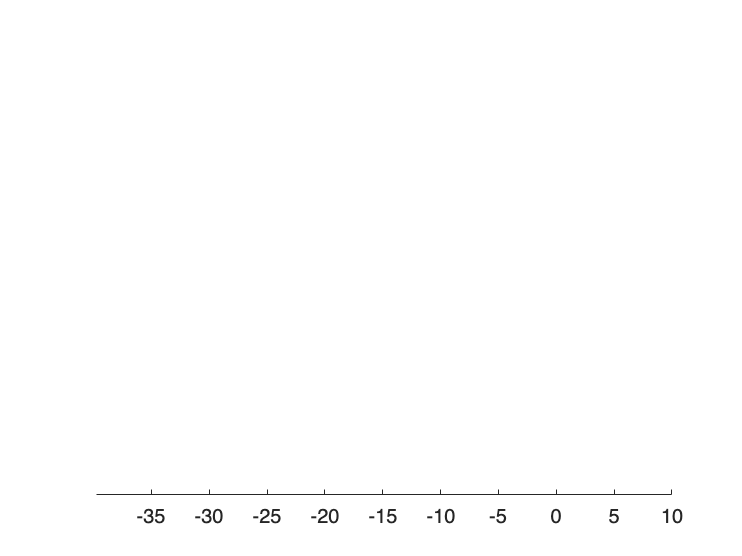


%% Resulting optimal parameters for Centralized case
% pVals = [0.0053    0.0451    0.0444    0.0453    0.0450] % after all tweaks (centralized)
%% Resulting optimal parameters for Decentralized case
% pVals = [0.1995    0.1282    0.2070    0.1636    0.2022] % after all tweaks (centralized)

%% An alternative: Trying some fixed set of parameters.
% pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));
%% Some other alternatives:
% pVals = [0.0203    0.0203    0.0202    0.0202    0.0204] % with initial condition 0.15
% pVals = [0.0029    0.0029    0.0028    0.0029    0.0029] % with initial condition 0.1


%%% Execution of the controller synthesis
%net.platoons(1).vehicles(2).synthesizeLocalControllers(2,nuBar,rhoBar)
% Actually, above defined nuBar,rhoBar,gammaSqBar are no longer needed

net.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

%%% In decentralized implementation, there are two things to consider:
% gammaSq_i needs to be costrainted at each subsystem i (or penalized considerably), 
% otherwise it tends to grow with i. Recall that max(gammaSq_i) = gammaSq. 
% There is a zero eigenvalue in the main LMI constraint (this is also in the
% centralized problem). This may be the reason why solver gives "Unknown Status" error.

%%% Graphing the Resulting topology
figure(2)
hold on
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(2)

Running the Simulation - Updating the states

% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10; 
tArray = 0:dt:tMax;

% Leader's trajectory specification
tVals = tMax*[0,0.2,0.4,0.6,0.8,1];     % Special time instants (inbetween which the acceleration is constant)
vVals = [0,30,40,40,20,20];  % Velocities to be achived at these time instants
net.generateLeadersControlProfiles(dt,tVals,vVals);

% Updating the platoons
for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(t,dt);
    net.redrawNetwork(2)
    pause(0.01)
    
end

% Plot the state histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

% Plot the location error histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{x}(t)$/location-error(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{v}(t)$/velocity-error(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 


% Plot the state histories of leaders
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 


figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

Ideas to pursue next:

What is the best set of passivity information for this topology synthesis?

Leader's connection design (Centralized Setting, ED-I)

For the case with z = C e

Local controller design for passivation